# Regularization Methods for Image Deblurring

This script implements and compares four regularization methods:

1. Tikhonov Regularization (iterative, for full images)

 2. Truncated SVD (TSVD) (spectral, for small patches) 

3. NSIT + Morozov Discrepancy Principle (iterative, for full images) 

4. FNSIT - Fast Non-Stationary Iterated Tikhonov (iterative, for full images)

clear; clc; close all;

## Mathematical Background

**Inverse Problem:**

We consider the linear inverse problem of recovering an image $x$ from noisy blurred observations $y$:


$$y = Ax + \varepsilon, \quad \varepsilon \sim \mathcal{N}(0, \sigma^2 I)$$


where $A : \mathbb{R}^N \to \mathbb{R}^N$ is a Gaussian blur (convolution) operator and $\varepsilon$ represents additive Gaussian noise with standard deviation $\sigma$.

**Ill-posedness:**

The operator $A$ is ill-conditioned: its singular values $\sigma_i$ decay rapidly towards zero. The naive pseudoinverse solution


$$x^\dagger = A^\dagger y = \sum_{i=1}^{r} \frac{u_i^T y}{\sigma_i} v_i$$


amplifies noise through the small singular values, making direct inversion unstable. Regularization methods stabilise the inversion by imposing additional constraints on the solution.

**Error Metrics:**


$$\text{MSE} = \frac{1}{N}\sum_{i=1}^{N}(x_i^{\text{rec}} - x_i^{\text{true}})^2$$



$$\text{Relative Error} = \frac{\|x^{\text{rec}} - x^{\text{true}}\|}{\|x^{\text{true}}\|}$$


## Part 1: Common Setup

## 1.1 Load Image

%img = imread('296059.jpg');
img = imread("C:\Desktop\Sem 4\inverse-problems-regularization\Matlab_Codes_Images\toy.png");
if ndims(img) == 3
    img = rgb2gray(img);
end
x_true = double(img);
x_true = x_true / max(x_true(:));

[rows, cols] = size(x_true);
fprintf('Image size: %d x %d\n', rows, cols);

Image size: 481 x 493


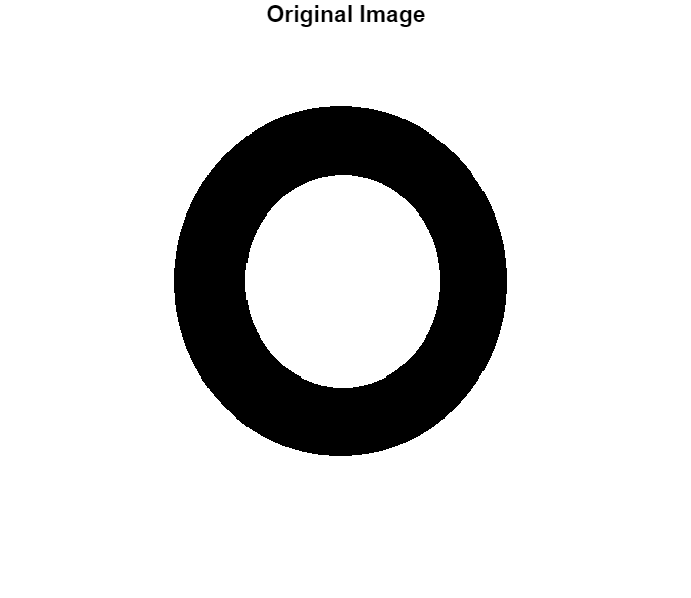


figure;
imshow(x_true, []);
title('Original Image');

## 1.2 Gaussian Blur Kernel

**Gaussian Point Spread Function (PSF):**


$$h(i,j) = \frac{1}{Z} \exp\!\left(-\frac{i^2 + j^2}{2\sigma_k^2}\right), \quad Z = \sum_{i,j} h(i,j)$$


The kernel $h$ is normalised so that $\sum h(i,j) = 1$ (energy-preserving).

kernel_size = 9;
sigma = 2.0;

half_size = floor(kernel_size / 2);
[xx, yy] = meshgrid(-half_size:half_size, -half_size:half_size);
kernel = exp(-(xx.^2 + yy.^2) / (2 * sigma^2));
kernel = kernel / sum(kernel(:));

## 1.3 Forward Model: y = Ax + noise

**Forward model:**


$$y = h * x + \varepsilon$$


where $*$ denotes 2D convolution with symmetric boundary conditions.

**Adjoint operator** $A^T$: convolution with the flipped kernel $h(-i,-j)$. For symmetric kernels $A^T \approx A$, but we implement the general case.

noise_std = 0.01;
rng(42);

Ax = A_op(x_true, kernel);
eps = noise_std * randn(size(Ax));
y = Ax + eps;

delta = norm(eps(:));
fprintf('Noise level delta = %.4f\n', delta);

Noise level delta = 4.8695


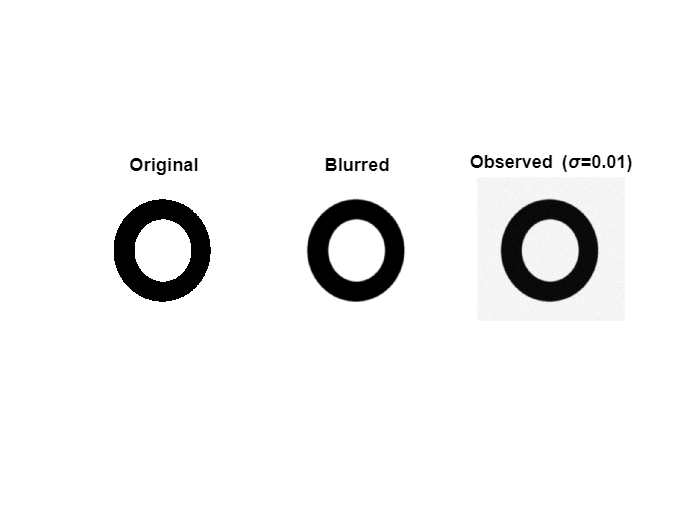


figure;
subplot(1,3,1); imshow(x_true, []); title('Original');
subplot(1,3,2); imshow(Ax, []);     title('Blurred');
subplot(1,3,3); imshow(y, []);      title(sprintf('Observed (\\sigma=%.2f)', noise_std));

## Part 2: Tikhonov Regularization (Full Image)

**Tikhonov variational formulation:**


$$x_\lambda = \arg\min_x \left\{ \|Ax - y\|^2 + \lambda \|x\|^2 \right\}$$


Setting the gradient to zero gives the **normal equation**:


$$(A^T A + \lambda I)\, x_\lambda = A^T y$$


Since forming $A^T A$ explicitly is infeasible for large images, we solve via **gradient descent**:


$$x^{(k+1)} = x^{(k)} - \tau \left[ A^T(Ax^{(k)} - y) + \lambda\, x^{(k)} \right]$$


where $\tau > 0$ is the step size.

**Role of** $\lambda$**:**

- $\lambda$ small $\Rightarrow$ less regularization, closer to naive inversion (noisy)

- $\lambda$ large $\Rightarrow$ more smoothing, loss of fine details

**Spectral interpretation:** In the SVD basis, Tikhonov applies the filter


$$f_i^\lambda = \frac{\sigma_i^2}{\sigma_i^2 + \lambda}$$


which smoothly damps components with $\sigma_i^2 \ll \lambda$.

fprintf('\n--- TIKHONOV REGULARIZATION ---\n');


--- TIKHONOV REGULARIZATION ---


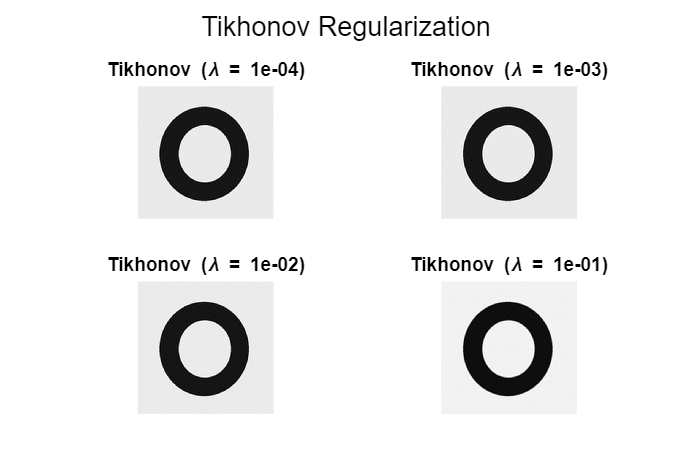

lambda = 1e-04 : Relative error = 0.0540, MSE = 0.002228
lambda = 1e-03 : Relative error = 0.0541, MSE = 0.002232
lambda = 1e-02 : Relative error = 0.0553, MSE = 0.002335
lambda = 1e-01 : Relative error = 0.1083, MSE = 0.008954



lambdas = [1e-4, 1e-3, 1e-2, 1e-1];

figure('Position', [100, 100, 1200, 800]);
sgtitle('Tikhonov Regularization');

for i = 1:length(lambdas)
    lam = lambdas(i);
    x_tik = tikhonov_reconstruction(y, kernel, lam, 200, 0.1);
    
    err = norm(x_tik(:) - x_true(:)) / norm(x_true(:));
    mse_val = mean((x_tik(:) - x_true(:)).^2);
    fprintf('lambda = %.0e : Relative error = %.4f, MSE = %.6f\n', lam, err, mse_val);
    
    subplot(2, 2, i);
    imagesc(x_tik); colormap gray; axis image off;
    title(sprintf('Tikhonov (\\lambda = %.0e)', lam));
end


% Best Tikhonov
x_tik_best = tikhonov_reconstruction(y, kernel, 1e-4, 200, 0.1);
err_tik = norm(x_tik_best(:) - x_true(:)) / norm(x_true(:));
mse_tik = mean((x_tik_best(:) - x_true(:)).^2);
fprintf('Best Tikhonov: Relative error = %.4f, MSE = %.6f\n', err_tik, mse_tik);

Best Tikhonov: Relative error = 0.0540, MSE = 0.002228


## Part 3: Truncated SVD (16x16 Patch Only)

**SVD of the blur matrix:**


$$A = U \Sigma V^T = \sum_{i=1}^{r} \sigma_i\, u_i\, v_i^T$$


where $\sigma_1 \geq \sigma_2 \geq \cdots \geq \sigma_r > 0$ are the singular values, and $\{u_i\}, \{v_i\}$ are the left/right singular vectors.

**TSVD reconstruction (keep first** $k$** components):**


$$x_k = \sum_{i=1}^{k} \frac{u_i^T y}{\sigma_i}\, v_i = V_k \Sigma_k^{-1} U_k^T y$$


For $i > k$, the noise-dominated terms $\frac{u_i^T \varepsilon}{\sigma_i}$ are discarded.

**Choice of** $k$**:**

- Small $k$ $\Rightarrow$ heavy regularization, smooth but blurry

- Large $k$ $\Rightarrow$ less filtering, noise starts to appear

The optimal $k$ balances approximation error and noise propagation.

**Note:** Forming the explicit matrix $A \in \mathbb{R}^{N \times N}$ is only feasible for small $N$. We extract a 16$\times$16 patch ($N = 256$).

fprintf('\n--- TRUNCATED SVD (16x16 PATCH) ---\n');


--- TRUNCATED SVD (16x16 PATCH) ---



% Extract 16x16 patch
patch = x_true(101:116, 101:116);
patch = patch / max(patch(:));
n_patch = size(patch, 1);

% Build explicit blur matrix for patch
A_matrix = build_blur_matrix(kernel, n_patch);

% Forward model on patch
Ax_patch = A_op(patch, kernel);
eps_patch = noise_std * randn(size(Ax_patch));
y_patch = Ax_patch + eps_patch;

% SVD
[U, S_mat, V] = svd(A_matrix, 'econ');
S = diag(S_mat);
fprintf('Condition number of A: %.2e\n', S(1)/S(end));

Condition number of A: 5.87e+07


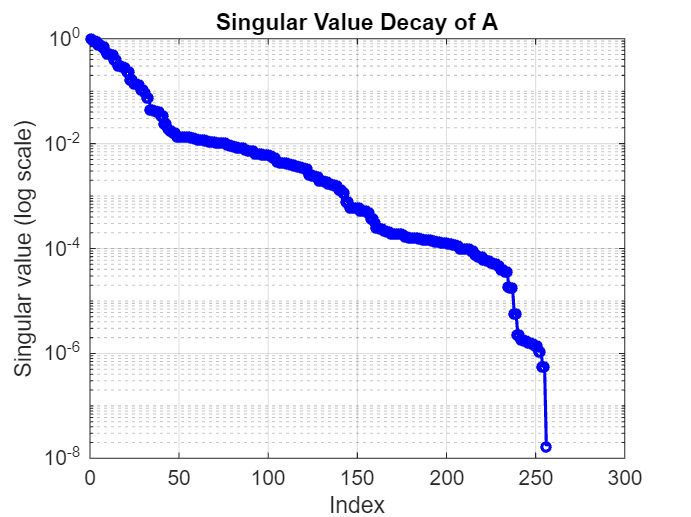


x_vec = patch(:);
y_vec = y_patch(:);

% Plot singular value decay
figure;
semilogy(S, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Index');
ylabel('Singular value (log scale)');
title('Singular Value Decay of A');
grid on;

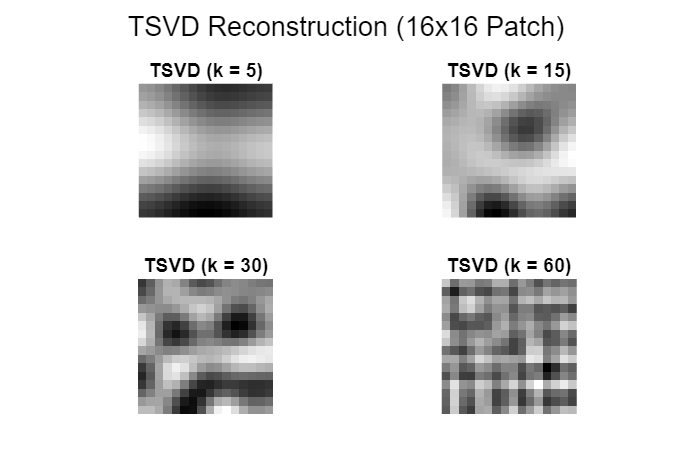

k =  5 : Relative error = 0.0019
k = 15 : Relative error = 0.0042
k = 30 : Relative error = 0.0106
k = 60 : Relative error = 0.1183



% TSVD with different k values
ks = [5, 15, 30, 60];
figure('Position', [100, 100, 1200, 800]);
sgtitle('TSVD Reconstruction (16x16 Patch)');

for i = 1:length(ks)
    k = ks(i);
    x_tsvd = tsvd_reconstruction(U, S, V, y_vec, k);
    x_tsvd_img = reshape(x_tsvd, [n_patch, n_patch]);
    
    err = norm(x_tsvd - x_vec) / norm(x_vec);
    fprintf('k = %2d : Relative error = %.4f\n', k, err);
    
    subplot(2, 2, i);
    imagesc(x_tsvd_img); colormap gray; axis image off;
    title(sprintf('TSVD (k = %d)', k));
end


% Error vs truncation index
errors_tsvd = zeros(length(S)-1, 1);
for k = 1:length(S)-1
    x_k = tsvd_reconstruction(U, S, V, y_vec, k);
    errors_tsvd(k) = norm(x_k - x_vec) / norm(x_vec);
end

[best_err_tsvd, best_k] = min(errors_tsvd);
mse_tsvd = mean((tsvd_reconstruction(U, S, V, y_vec, best_k) - x_vec).^2);
fprintf('Best k = %d : Relative error = %.4f, MSE = %.6f\n', best_k, best_err_tsvd, mse_tsvd);

Best k = 1 : Relative error = 0.0000, MSE = 0.000000


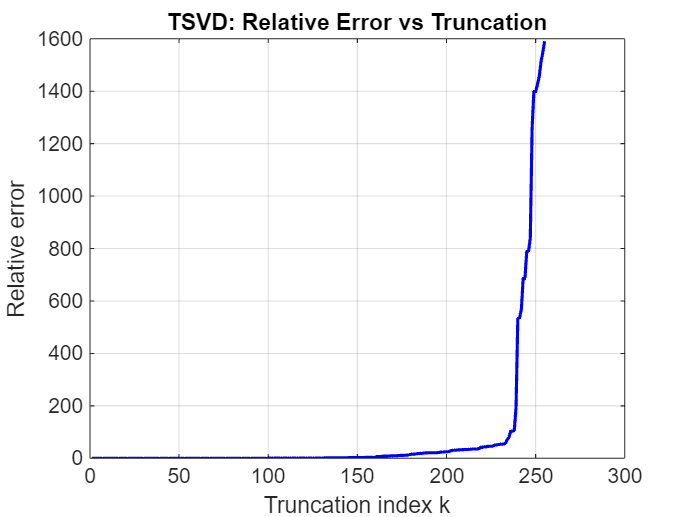


figure;
plot(1:length(errors_tsvd), errors_tsvd, 'b-', 'LineWidth', 1.5);
xlabel('Truncation index k');
ylabel('Relative error');
title('TSVD: Relative Error vs Truncation');
grid on;

## Part 4: NSIT + Morozov Discrepancy (Full Image)

**Non-Stationary Iterated Tikhonov (NSIT):**

At each iteration $n$, we compute a correction by solving:


$$(A^T A + \alpha_n I)\, z_n = A^T r_n, \quad r_n = y - Ax_n$$


and update:


$$x_{n+1} = x_n + z_n$$


**Non-stationary regularization schedule:**


$$\alpha_n = \alpha_0 \cdot q^n, \quad q \in (0,1)$$


The decaying sequence $\{\alpha_n\}$ starts with strong regularization (large $\alpha_0$) and gradually reduces it, allowing finer corrections as the residual decreases. This is the key difference from standard (stationary) iterated Tikhonov where $\alpha$ is fixed.

**Inner solver:** The linear system $(A^T A + \alpha_n I) z = \text{rhs}$ is solved approximately by gradient descent:


$$z^{(j+1)} = z^{(j)} - s \left[ A^T A z^{(j)} + \alpha_n z^{(j)} - \text{rhs} \right]$$


**Morozov discrepancy principle (stopping rule):**


$$\|Ax_n - y\| \leq \tau \cdot \delta, \quad \tau > 1$$


where $\delta = \|\varepsilon\|$ is the noise level. This stops iteration when the residual matches the noise level, preventing over-fitting.

fprintf('\n--- NSIT + MOROZOV DISCREPANCY ---\n');


--- NSIT + MOROZOV DISCREPANCY ---



n_iter_max = 50;
alpha0 = 1e-1;
q = 0.7;
tau = 1.05;

[x_nsit, residuals_nsit, errors_nsit, stop_iter_nsit] = ...
    nsit_morozov(y, x_true, kernel, delta, alpha0, q, tau, n_iter_max);

Iter 01 | alpha=1.00e-01 | residual=4.200e+01 | error=0.1163
Iter 02 | alpha=7.00e-02 | residual=6.350e+00 | error=0.0587
Iter 03 | alpha=4.90e-02 | residual=5.121e+00 | error=0.0562
Iter 04 | alpha=3.43e-02 | residual=4.944e+00 | error=0.0551
Morozov discrepancy satisfied at iteration 4



fprintf('Stopped at iteration %d\n', stop_iter_nsit);

Stopped at iteration 4


fprintf('Final relative error: %.4f\n', errors_nsit(end));

Final relative error: 0.0551


mse_nsit = mean((x_nsit(:) - x_true(:)).^2);
fprintf('MSE = %.6f\n', mse_nsit);

MSE = 0.002313


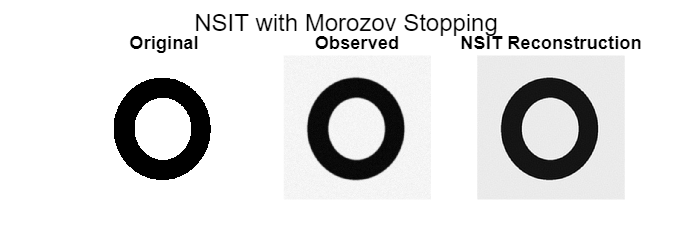


% Visualization
figure('Position', [100, 100, 1200, 400]);
subplot(1, 3, 1); imagesc(x_true); colormap gray; axis image off; title('Original');
subplot(1, 3, 2); imagesc(y); colormap gray; axis image off; title('Observed');
subplot(1, 3, 3); imagesc(x_nsit); colormap gray; axis image off; title('NSIT Reconstruction');
sgtitle('NSIT with Morozov Stopping');

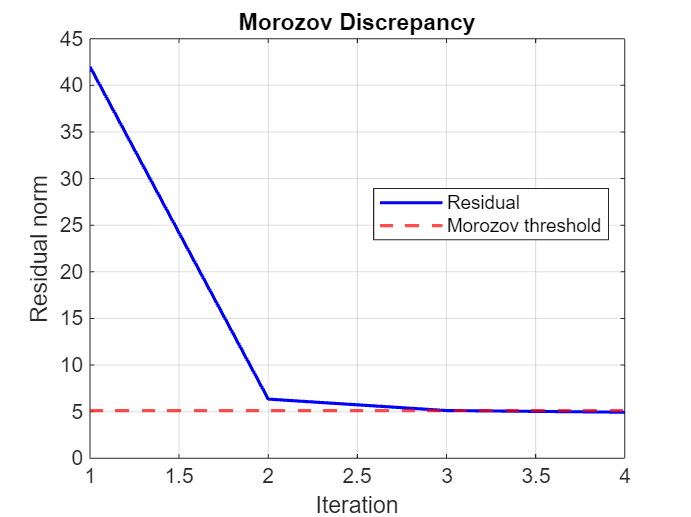


% Residual plot
figure;
plot(1:length(residuals_nsit), residuals_nsit, 'b-', 'LineWidth', 1.5);
hold on;
yline(tau * delta, 'r--', 'LineWidth', 1.5);
hold off;
xlabel('Iteration');
ylabel('Residual norm');
title('Morozov Discrepancy');
legend('Residual', 'Morozov threshold', 'Location', 'best');
grid on;

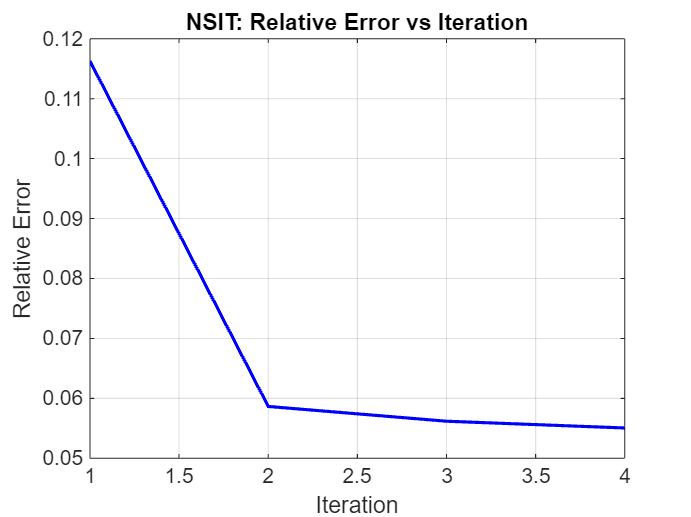


% Error plot
figure;
plot(1:length(errors_nsit), errors_nsit, 'b-', 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Relative Error');
title('NSIT: Relative Error vs Iteration');
grid on;

## Part 5: FNSIT — Fast Non-Stationary Iterated Tikhonov

**Motivation:** Standard NSIT applies a single correction per iteration. FNSIT introduces a **double-correction** that compensates for the regularization bias, achieving faster convergence.

**FNSIT update rule:**

Given residual $r_n = y - Ax_n$, compute two corrections:

**First correction** (standard Tikhonov update):


$$F_1 = (A^T A + \alpha_n I)^{-1} A^T r_n$$


**Second correction** (bias compensation):


$$F_2 = \alpha_n\, (A^T A + \alpha_n I)^{-1} (A^T A + \alpha_n^2 I)^{-1} A^T r_n$$


**Combined update:**


$$x_{n+1} = x_n + F_1 + F_2$$


**Why does** $F_2$** help?**

The standard Tikhonov correction $F_1$ introduces a bias because the regularization term $\alpha_n \|x\|^2$ shrinks the solution towards zero. The second correction $F_2$ partially undoes this shrinkage by applying an additional solve with $\alpha_n^2$ (which targets the squared-bias component) and then re-regularizing with $\alpha_n$.

**Theoretical convergence:**

Under standard source conditions, FNSIT achieves optimal convergence rates with fewer iterations than NSIT, because each step extracts more information from the residual.

**Regularization schedule and stopping:**


$$\alpha_n = \alpha_0 \cdot q^n, \quad \|Ax_n - y\| \leq \tau \cdot \delta$$


fprintf('\n--- FNSIT (Fast NSIT) ---\n');


--- FNSIT (Fast NSIT) ---



alpha0_f = 0.1;
q_f = 0.9;
tau_f = 1.05;
n_iter_max_f = 40;

[x_fnsit, residuals_fnsit, errors_fnsit, stop_iter_fnsit] = ...
    fnsit_morozov(y, x_true, kernel, delta, alpha0_f, q_f, tau_f, n_iter_max_f);

Iter 01 | alpha=1.00e-01 | residual=7.335e+00 | error=0.0611
Iter 02 | alpha=9.00e-02 | residual=5.206e+00 | error=0.0567
Iter 03 | alpha=8.10e-02 | residual=4.957e+00 | error=0.0552
Morozov satisfied at iteration 3



fprintf('Stopped at iteration %d\n', stop_iter_fnsit);

Stopped at iteration 3


fprintf('Final relative error: %.4f\n', errors_fnsit(end));

Final relative error: 0.0552


mse_fnsit = mean((x_fnsit(:) - x_true(:)).^2);
fprintf('MSE = %.6f\n', mse_fnsit);

MSE = 0.002322


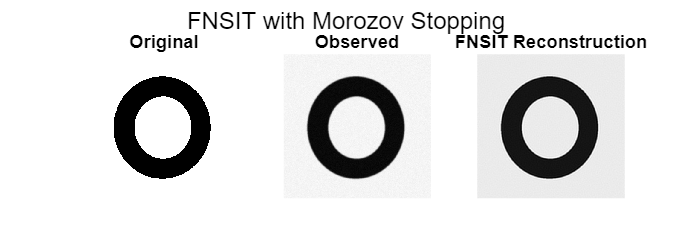


% Visualization
figure('Position', [100, 100, 1200, 400]);
subplot(1, 3, 1); imagesc(x_true); colormap gray; axis image off; title('Original');
subplot(1, 3, 2); imagesc(y); colormap gray; axis image off; title('Observed');
subplot(1, 3, 3); imagesc(x_fnsit); colormap gray; axis image off; title('FNSIT Reconstruction');
sgtitle('FNSIT with Morozov Stopping');

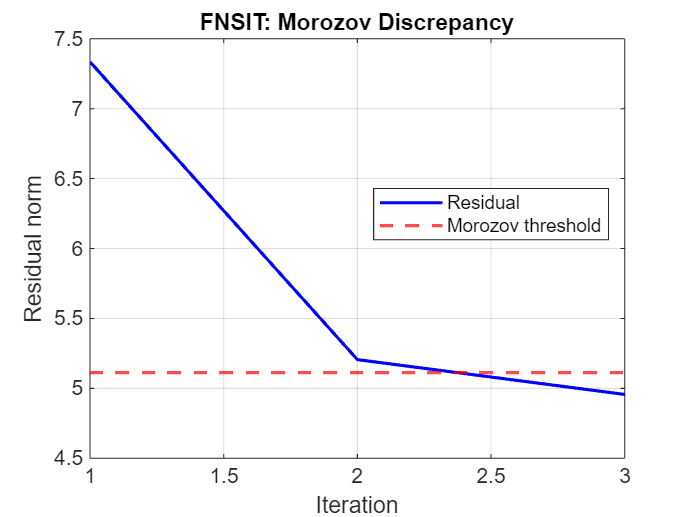


% Residual plot
figure;
plot(1:length(residuals_fnsit), residuals_fnsit, 'b-', 'LineWidth', 1.5);
hold on;
yline(tau_f * delta, 'r--', 'LineWidth', 1.5);
hold off;
xlabel('Iteration');
ylabel('Residual norm');
title('FNSIT: Morozov Discrepancy');
legend('Residual', 'Morozov threshold', 'Location', 'best');
grid on;

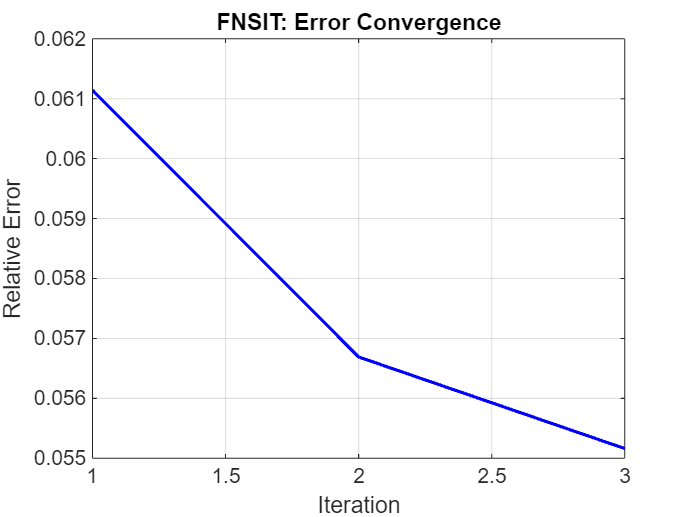


% Convergence plot
figure;
plot(1:length(errors_fnsit), errors_fnsit, 'b-', 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Relative Error');
title('FNSIT: Error Convergence');
grid on;

## Part 6: Comparison of All Methods

fprintf('\n--- FINAL COMPARISON ---\n');


--- FINAL COMPARISON ---



fprintf('%-15s  %15s  %15s\n', 'Method', 'Relative Error', 'MSE');

Method            Relative Error              MSE


fprintf('%s\n', repmat('-', 1, 50));

--------------------------------------------------


fprintf('%-15s  %15.4f  %15.6f\n', 'Tikhonov', err_tik, mse_tik);

Tikhonov                  0.0540         0.002228


fprintf('%-15s  %15.4f  %15.6f\n', 'TSVD (patch)', best_err_tsvd, mse_tsvd);

TSVD (patch)              0.0000         0.000000


fprintf('%-15s  %15.4f  %15.6f\n', 'NSIT', errors_nsit(end), mse_nsit);

NSIT                      0.0551         0.002313


fprintf('%-15s  %15.4f  %15.6f\n', 'FNSIT', errors_fnsit(end), mse_fnsit);

FNSIT                     0.0552         0.002322


fprintf('%s\n', repmat('-', 1, 50));

--------------------------------------------------


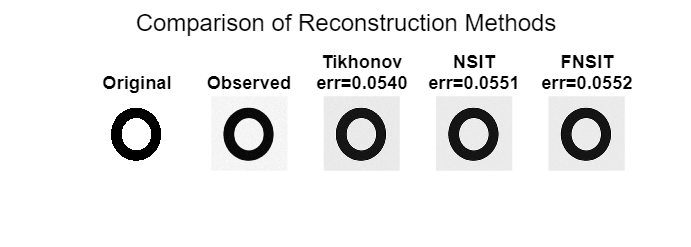


% Comparison figure (full-image methods only)
figure('Position', [100, 100, 1400, 500]);
subplot(1, 5, 1); imagesc(x_true); colormap gray; axis image off;
title('Original');
subplot(1, 5, 2); imagesc(y); colormap gray; axis image off;
title('Observed');
subplot(1, 5, 3); imagesc(x_tik_best); colormap gray; axis image off;
title(sprintf('Tikhonov\nerr=%.4f', err_tik));
subplot(1, 5, 4); imagesc(x_nsit); colormap gray; axis image off;
title(sprintf('NSIT\nerr=%.4f', errors_nsit(end)));
subplot(1, 5, 5); imagesc(x_fnsit); colormap gray; axis image off;
title(sprintf('FNSIT\nerr=%.4f', errors_fnsit(end)));
sgtitle('Comparison of Reconstruction Methods');

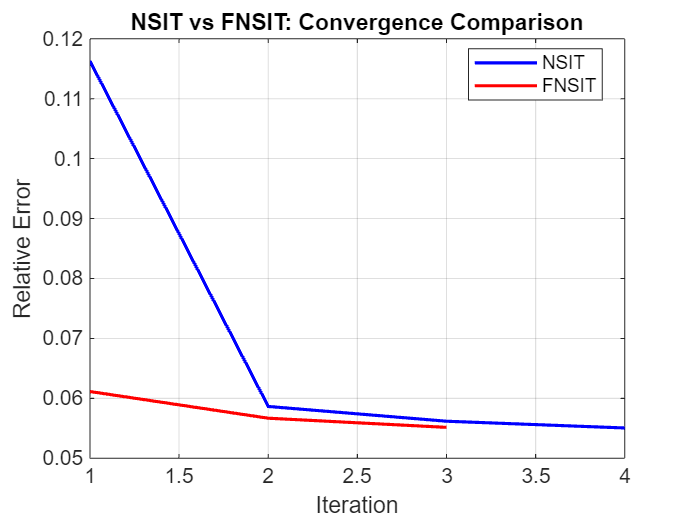


% NSIT vs FNSIT convergence
figure;
plot(1:length(errors_nsit), errors_nsit, 'b-', 'LineWidth', 1.5); hold on;
plot(1:length(errors_fnsit), errors_fnsit, 'r-', 'LineWidth', 1.5); hold off;
xlabel('Iteration');
ylabel('Relative Error');
title('NSIT vs FNSIT: Convergence Comparison');
legend('NSIT', 'FNSIT', 'Location', 'best');
grid on;

## FUNCTION DEFINITIONS

## Function: Forward Operator A (Blur)

function Ax = A_op(x, kernel)
Ax = imfilter(x, kernel, 'symmetric', 'same');
end

## Function: Adjoint Operator A^T (Correlation)

function ATx = AT_op(x, kernel)
% Adjoint of convolution = correlation = convolution with flipped kernel
kernel_flipped = rot90(kernel, 2);
ATx = imfilter(x, kernel_flipped, 'symmetric', 'same');
end

## Function: Tikhonov Reconstruction (Gradient Descent)

function x_rec = tikhonov_reconstruction(y, kernel, lam, n_iter, step)
% Solves: min ||Ax - y||^2 + lambda*||x||^2 via gradient descent
x_rec = zeros(size(y));
for iter = 1:n_iter
    residual = A_op(x_rec, kernel) - y;
    grad = AT_op(residual, kernel) + lam * x_rec;
    x_rec = x_rec - step * grad;
end
end

## Function: Build Explicit Blur Matrix (for small patches only)

function A = build_blur_matrix(kernel, n)
% Builds N x N blur matrix where N = n*n. Only feasible for small n.
N = n * n;
A = zeros(N, N);
for i = 1:N
    basis = zeros(n, n);
    basis(i) = 1.0;
    blurred = imfilter(basis, kernel, 'symmetric', 'same');
    A(:, i) = blurred(:);
end
end

## Function: Truncated SVD Reconstruction

function x_rec = tsvd_reconstruction(U, S, V, y_vec, k)
% TSVD: keep first k singular components
Uk = U(:, 1:k);
Sk = S(1:k);
Vk = V(:, 1:k);
x_rec = Vk * (Uk' * y_vec ./ Sk);
end

## Function: Inner Solver (Gradient Descent)

function z = solve_inner(rhs, kernel, alpha, n_inner, step)
% Approximately solves (A^T A + alpha*I) z = rhs via gradient descent
z = zeros(size(rhs));
for iter = 1:n_inner
    grad = AT_op(A_op(z, kernel), kernel) + alpha * z - rhs;
    z = z - step * grad;
end
end

## Function: NSIT with Morozov Discrepancy Principle

function [x_rec, residuals, errors, stop_iter] = ...
    nsit_morozov(y, x_true, kernel, delta, alpha0, q, tau, n_iter_max)
x_rec = zeros(size(y));
residuals = [];
errors = [];
stop_iter = n_iter_max;

for n = 1:n_iter_max
    alpha_n = alpha0 * (q ^ (n-1));
    
    % Compute residual
    r = y - A_op(x_rec, kernel);
    rhs = AT_op(r, kernel);
    
    % Solve inner problem and update
    update = solve_inner(rhs, kernel, alpha_n, 20, 0.2);
    x_rec = x_rec + update;
    
    % Track residual norm
    res_norm = norm(A_op(x_rec, kernel) - y, 'fro');
    residuals = [residuals; res_norm];
    
    % Track error
    err = norm(x_rec(:) - x_true(:)) / norm(x_true(:));
    errors = [errors; err];
    
    fprintf('Iter %02d | alpha=%.2e | residual=%.3e | error=%.4f\n', ...
        n, alpha_n, res_norm, err);
    
    % Check Morozov stopping
    if res_norm <= tau * delta
        fprintf('Morozov discrepancy satisfied at iteration %d\n', n);
        stop_iter = n;
        break;
    end
end
end

## Function: FNSIT with Morozov Discrepancy Principle

function [x_rec, residuals, errors, stop_iter] = ...
    fnsit_morozov(y, x_true, kernel, delta, alpha0, q, tau, n_iter_max)
x_rec = zeros(size(y));
residuals = [];
errors = [];
stop_iter = n_iter_max;

for n = 1:n_iter_max
    alpha_n = alpha0 * (q^(n-1));
    
    % Residual
    r = y - A_op(x_rec, kernel);
    
    % F1: standard Tikhonov correction
    F1 = solve_inner(AT_op(r, kernel), kernel, alpha_n, 20, 0.2);
    
    % F2: bias-compensating correction
    temp = solve_inner(AT_op(r, kernel), kernel, alpha_n^2, 20, 0.2);
    F2 = alpha_n * solve_inner(temp, kernel, alpha_n, 20, 0.2);
    
    % Double-correction update
    x_rec = x_rec + F1 + F2;
    
    % Track residual norm
    res_norm = norm(A_op(x_rec, kernel) - y, 'fro');
    residuals = [residuals; res_norm];
    
    % Track error
    err = norm(x_rec(:) - x_true(:)) / norm(x_true(:));
    errors = [errors; err];
    
    fprintf('Iter %02d | alpha=%.2e | residual=%.3e | error=%.4f\n', ...
        n, alpha_n, res_norm, err);
    
    % Morozov stopping
    if res_norm <= tau * delta
        stop_iter = n;
        fprintf('Morozov satisfied at iteration %d\n', n);
        break;
    end
end
end